# Acc Movement Classification Tester Script:

## Load Data:

load("/Users/kylewimmer/Documents/2021/Speech_Project/Data_Collection/Programs/APP/Session1/Session1_DataTab.mat");

## Run Function:

[totalAcc,bodyAcc_Sum,TimeAcc_Seg,moveYN] = polarMoveClassi_func(dataTab.ACC,dataTab.accTimestamps);

## Plot Original Acc Data:

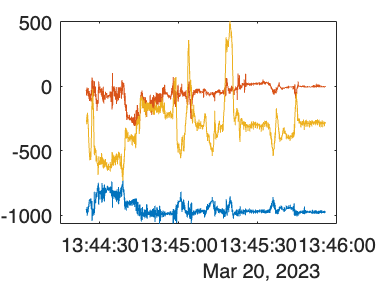

figure;
plot(dataTab.accTimestamps{1},dataTab.ACC{1});

## Plot Processed Data:

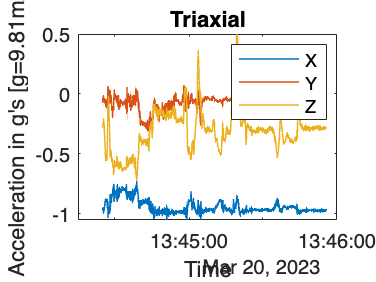

figure;
proAxis = axes;
plot(proAxis,dataTab.accTimestamps{1},totalAcc{1},'LineWidth',0.75);
legend('X','Y','Z');
ylabel(proAxis,"Acceleration in g's [g=9.81m/s]");
xlabel(proAxis,'Time');
title(proAxis,'Triaxial');

## Plot Summed Movement:

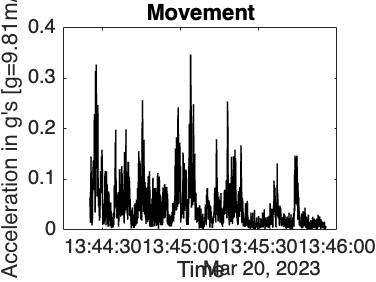

figure;
moveAxis = axes;
plot(moveAxis,dataTab.accTimestamps{1},bodyAcc_Sum{1},"Color",'black','LineWidth',0.75);
ylabel(moveAxis,"Acceleration in g's [g=9.81m/s]");
xlabel(moveAxis,'Time');
title(moveAxis,'Movement')

## Plot Results:

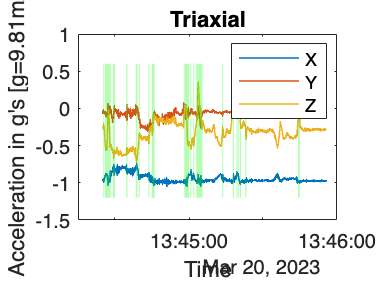

clrs = {'white','green'};
dispAnalysis(proAxis,moveYN{1},TimeAcc_Seg{1},clrs);

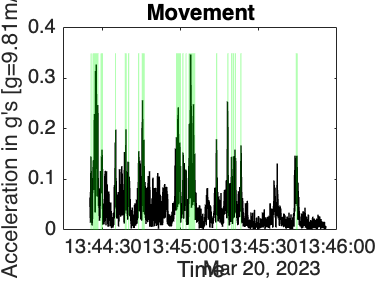

dispAnalysis(moveAxis,moveYN{1},TimeAcc_Seg{1},clrs); % Has the addition to add the desired yLims - For subplots in overview tab

## Functions:

function dispAnalysis(p_Axis,results,rTimeFrames,clrs,YLims)
    % Display the analysis results as filled areas:
    % Find Changes:
    chgPts_Idx = find(diff(results)~=0)+1;
    % Get Corresponding Colours:
    idxClrs = results(chgPts_Idx,1)+1;
    % Y-Coordinates:
    if ~exist("YLims","var")
        YLims = ylim(p_Axis);
    end
    yCoords = [YLims(1) YLims(1) ...
        YLims(2) YLims(2)];
    for ii=1:size(chgPts_Idx,1)-1
        if ~strcmpi(clrs{idxClrs(ii)},'white')
            % X-Coordinates:
            xCoords = [rTimeFrames(chgPts_Idx(ii),1) rTimeFrames(chgPts_Idx(ii+1)-1,2) ...
                rTimeFrames(chgPts_Idx(ii+1)-1,2) rTimeFrames(chgPts_Idx(ii),1)];
            % Plot Results:
            p = patch(p_Axis,xCoords,yCoords,clrs{idxClrs(ii)},'FaceAlpha',0.3,'EdgeColor','none');
            p.Annotation.LegendInformation.IconDisplayStyle = 'off';
        end
    end
%EOF
end